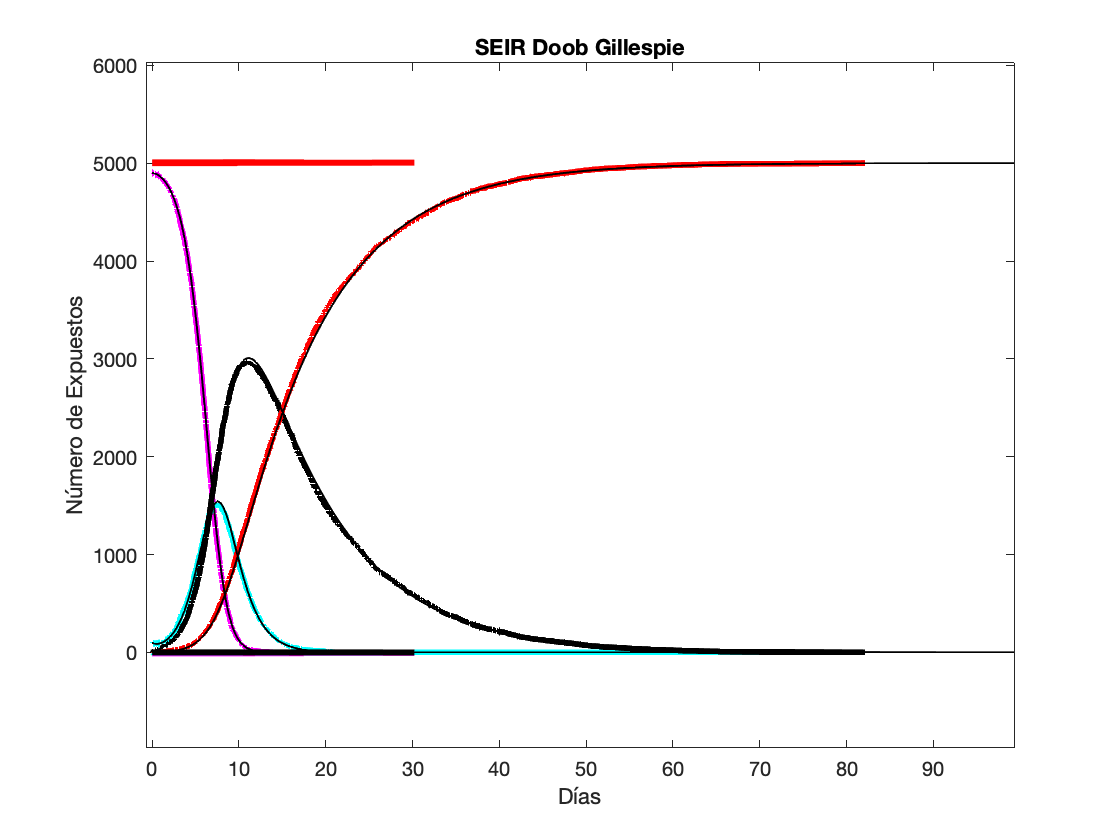

clc;
clear all;


tspan = [0 100];

y0 = [4899 100 1 0 1.8 0.1 0.5];

[tsol, ysol] = ode45(@SEIR_ODE, tspan, y0); 

% Variables
beta_param = 1.8;
gamma_param = 0.1;
sigma_param = 0.5;

% Condiciones iniciales
initial_S = 4899;
initial_E = 100;
initial_I = 1;
initial_R = 0;

% Número de simulaciones
numSimulations = 10;

% Duración de la simulación
endTime = 100;

% 10 simulaciones estocásticas
for sim = 1:numSimulations
    %[t, y] = gillespieSEIR(beta_param, gamma_param, sigma_param, initial_S, initial_E, initial_I, initial_R, endTime);
    t = 0;
    y = [initial_S, initial_E, initial_I, initial_R];

    while t(end) < endTime
        rates = [beta_param * initial_S * initial_I / (initial_S + initial_E + initial_I + initial_R), sigma_param * initial_E, gamma_param * initial_I];
        totalRate = sum(rates);

        % Generar dos números aleatorios para el paso de tiempo y el evento
        dt = -log(rand) / totalRate;
        event = find(rand * totalRate <= cumsum(rates), 1, 'first');

        % Actualizar variables según el evento
        if event == 1
            initial_S = initial_S - 1;
            initial_E = initial_E + 1;
        elseif event == 2
            initial_E = initial_E - 1;
            initial_I = initial_I + 1;
        elseif event == 3
            initial_I = initial_I - 1;
            initial_R = initial_R + 1;
        end

        t = [t, t(end) + dt];
        y = [y; initial_S, initial_E, initial_I, initial_R];
    end
    figure(2)
    plot(t, y(:, 1), 'm', 'LineWidth', 3);
    hold on;
    plot(t, y(:, 2), 'c', 'LineWidth', 3);
    plot(t, y(:, 3), 'k', 'LineWidth', 3);
    plot(t, y(:, 4), 'r', 'LineWidth', 3);
    title('SEIR Doob Gillespie');
    xlabel('Días');
    ylabel('Número de Expuestos');
end

plot(tsol, ysol(:, 1), 'Color', 'k', 'LineWidth', 1)
plot(tsol, ysol(:, 2), 'Color', 'k', 'LineWidth', 1)
plot(tsol, ysol(:, 3), 'Color', 'k', 'LineWidth', 1)
plot(tsol, ysol(:, 4), 'Color', 'k', 'LineWidth', 1)
hold off;

function dYdt = SEIR_ODE(t, Y)
    beta = Y(5);
    gamma = Y(6);
    sigma = Y(7);

    S = Y(1);
    E = Y(2);
    I = Y(3);
    R = Y(4);

    N = S + E + I + R;

    dSdt = -(beta * S * I) / N;
    dEdt = (beta * S * I) / N - sigma * E;
    dIdt = sigma * E - gamma * I;
    dRdt = gamma * I;
    dYdt = [dSdt; dEdt; dIdt; dRdt; 0; 0; 0];
end
